## Matlab code for generateing main figure 4 in the following paper:

[Single cell transcriptomics of human epidermis identifies basal stem cell transition states](https://www.nature.com/articles/s41467-020-18075-7), S. Wang, M. Drummond, C.Guerrero-Juarez, E.Tarapore, A.MacLean, A. Stabell, S. Wu, G. Gutierrez, B. That, C. Benavente, Q. Nie & S. X. Atwood, Nature Communications, 2020.

- All the results are generated by applying SoptSC to the single-cell rna-seq data, for detailed useage of SoptSC, please refer to

- [https://github.com/WangShuxiong/SoptSC](https://github.com/WangShuxiong/SoptSC)

- Some figures are generated using custermized code below

% Add tools into matlab path
addpath('Data');
addpath('NNDSVD');
addpath('symnmf2');
addpath('EE');
addpath('vinlinplot');
addpath('scTools');
addpath('scTools/graphViz2Mat1');
addpath('Cell_Cell_Communication');
addpath('gephi');
addpath('Results');

#### Step 1 (Required)

Load data

%% Step 1: load data
load Data_Figure4.mat;

% set folder to save all figures
folder = 'Results\Fig4';
folder1 = 'Results/Fig4';

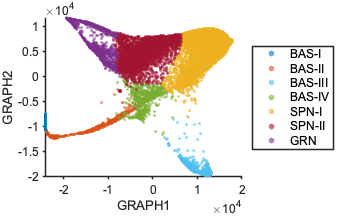

%% Fig4A
figname = 'Fig4A';
method = 'GRAPH';

No_cluster = Data_Figure4.No_cluster;
cluster_order = 1:No_cluster; % cluster orders for plots
plot_cluster(Data_Figure4.latent,Data_Figure4.cluster_label,Data_Figure4.No_cluster,Data_Figure4.cluster_legend,folder,...
    cluster_order,method,figname,Data_Figure4.cluster_color);

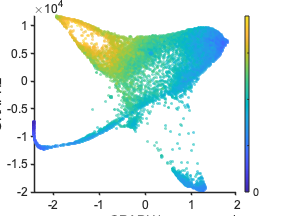

%% Fig4B

figname = 'Fig4B';
method = 'GRAPH';
plot_pseudotime(Data_Figure4.latent,Data_Figure4.pseudotime,folder,figname,method);

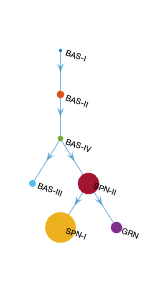

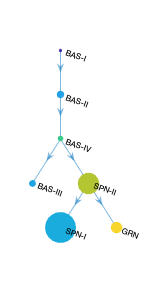

%%
figname = 'lineage_tree';

plot_lineage(Data_Figure4.Lineage,Data_Figure4.No_cluster,Data_Figure4.cluster_label,Data_Figure4.pseudotime,...
    Data_Figure4.cluster_legend,folder,Data_Figure4.cluster_color,figname);

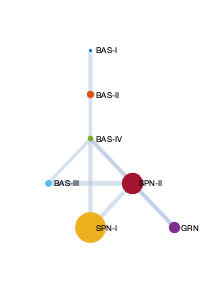

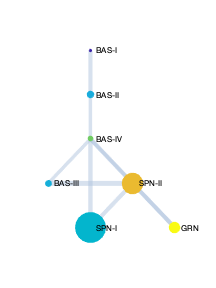

%% plot lineage by adding some new edges
No_added_edges = 3;
plot_lineage_weighted_all_edge(Data_Figure4.Lineage,Data_Figure4.No_cluster,Data_Figure4.cluster_label,...
    Data_Figure4.pseudotime,Data_Figure4.CC_adjacent,Data_Figure4.cluster_legend,No_added_edges,figname,folder,...

    Data_Figure4.cluster_color);

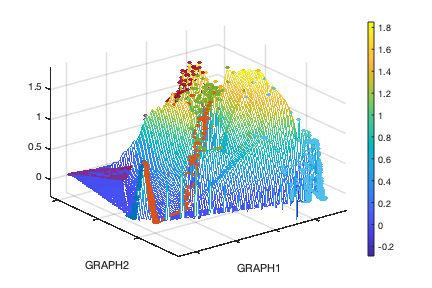

%% calculate energy for each cell
P = Data_Figure4.H'./sum(Data_Figure4.H,2)';
Energy = entropy(P);

%% Fig4D
figname = 'LandScape_Cells';
method = 'GRAPH';
plot_landscape(Data_Figure4.latent,Energy,Data_Figure4.cluster_label,Data_Figure4.cluster_color,folder,figname,method);

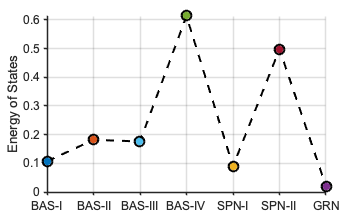

%% Energy value for each cluster
for i = 1:Data_Figure4.No_cluster
    E_plus_state(i) = mean(Energy(Data_Figure4.cluster_label==i));
end
%% Fig4E2
figname = 'State_Energy';
order = 1:Data_Figure4.No_cluster;
plot_state_energy(E_plus_state,order,Data_Figure4.cluster_legend,Data_Figure4.cluster_color,figname,folder);

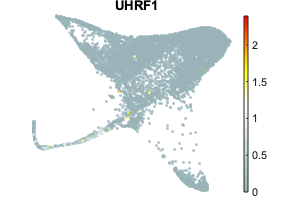

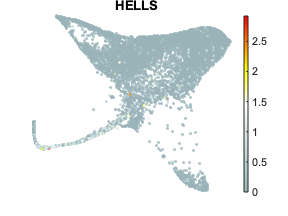

%%
% Fig4H, feature plots
Marker = {'UHRF1','HELLS'};
plot_feature(Data_Figure4.data,Marker,Data_Figure4.allgenes,Data_Figure4.latent,folder);

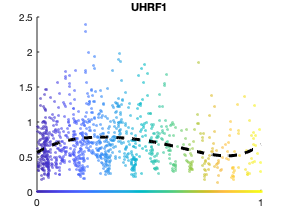

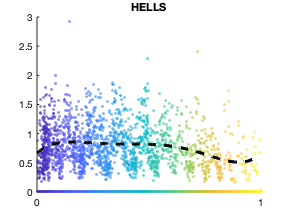


%% plot marker dynamics along pseudotime
for i = 1:2
    figure;
    plot_gene_along_ptime(Data_Figure4.data,Marker(i),Data_Figure4.pseudotime,Data_Figure4.allgenes,folder);
end